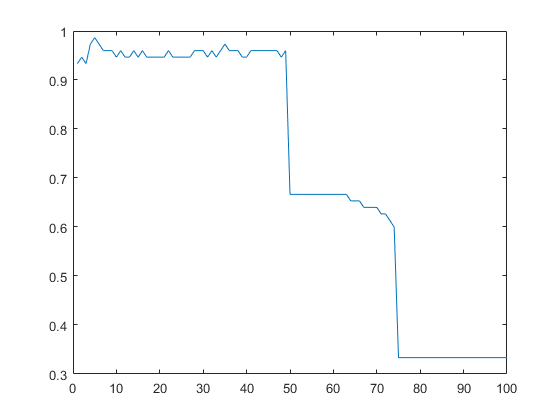

% Step 1: Load the fisheriris dataset
clc
clear
load fisheriris.mat

% Step 2: Extract the feature matrix X and class labels y
X = meas(:,3:4); % Feature matrix (150 samples x 4 features)
y = species; % Class labels (setosa, versicolor, virginica)

% Step 3: Split the data into training and testing sets
rng('default'); % For reproducibility
cv = cvpartition(y, 'Holdout', 0.3); % 70% training, 30% testing
X_train = X(training(cv), :);
y_train = y(training(cv));
X_test = X(test(cv), :);
y_test = y(test(cv));

num_neighbours = 5;
kNN_model = fitcknn(X_train,y_train, 'NumNeighbors', num_neighbours, 'Standardize', 1);

for i = 1:100
    kNN_model.NumNeighbors = i;
    y_pred = predict(kNN_model, X_test);
    conf = confusionmat(y_test, y_pred);
    correction_rate(i) = sum(diag(conf))/sum(conf,"all");
end
[M, I] = max(correction_rate);
plot(1:100, correction_rate)

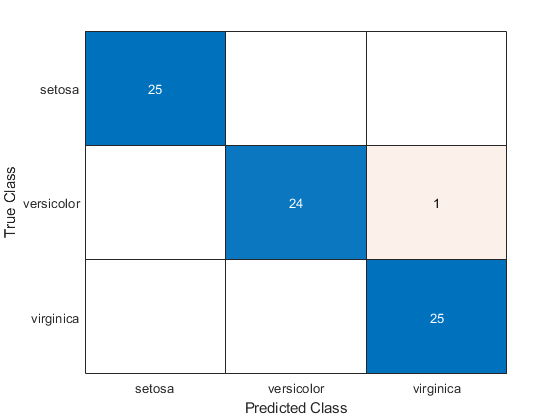

title('kNN correction rate');
xlabel('Correction rate');
ylabel('Number of neighbours');

kNN_model.NumNeighbors = I;
y_pred = predict(kNN_model, X_test);
C = confusionmat(y_test, y_pred);
confusionchart(y_test, y_pred);

disp('Confusion Matrix:');

Confusion Matrix:


disp(C);

    25     0     0
     0    24     1
     0     0    25



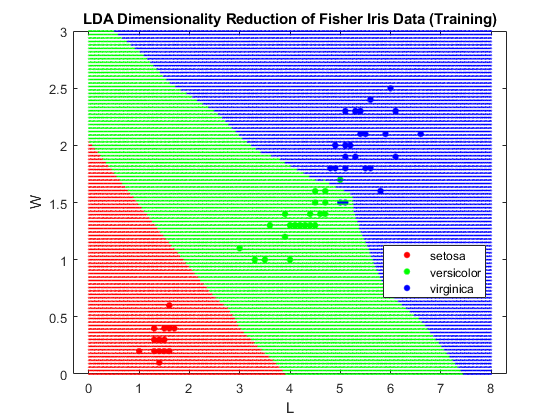

correction_rate = sum(diag(C))/sum(C,"all");

gscatter(X_train(:, 1), X_train(:, 2), y_train, 'rgb');
title('LDA Dimensionality Reduction of Fisher Iris Data (Training)');
xlabel('LDA Component 1');
ylabel('LDA Component 2');

[L, W] = meshgrid(linspace(0, 8, 500), linspace(0,3,100)); ...
L = L(:);
W = W(:);
pred = kNN_model.predict([L W]);
hold on;
h = gscatter(L, W, pred, 'rgb', '.', 1, 'off'); set(h, 'LineWidth', 2, 'MarkerSize', 2)
legend('setosa', 'versicolor', 'virginica', '', '', '');
hold off; 